Zad 1

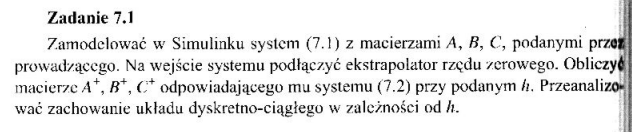

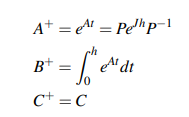

clear;
A = [0 2*pi ; -2*pi 0];
B = [1; 0];
C = [0 1];

h = 0.05;


[P, J] = jordan(A);

jordan requires Symbolic Math Toolbox.

e = exp(1);
syms t
% Definicja A_plus jako funkcji anonimowej
A_plus =@(h) P * expm(J * h) / P;
% Wyrażenie symboliczne dla e^(A*t)
expr = expm(A * t);
% Całkowanie wyrażenia symbolicznego od 0 do h
B_plus = int(expm(A * t) * B, t, 0, h);
% Obliczenie wartości całki dla t = h
B_plus_x = double(subs(B_plus, t, h));

% Wyjściowe wartości C_plus i D_plus
Cd = C;
Dd = 0;

Ad = double(A_plus(h))
Bd = double(B_plus)

Zad 2

Zad 3

Zad 4

Zad 5

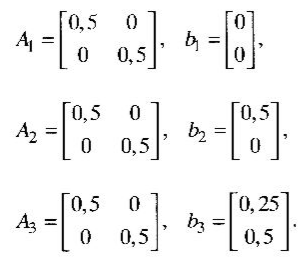

figure; hold on;
N=10000;
x=zeros(2,N);

A1 = [0.5 0; 0 0.5];
b1 = [0; 0];
A2 = A1; A3 = A1;
b2 = [0.5; 0];
b3 = [0.25; 0.5];

for a = 2 : N
    c=randi([0 2]);    
    switch c
        case 0    
            A = A1;
            b = b1;
        case 1
            A = A2;
            b = b2;
        case 2
            A = A3;
            b = b3;
    end
    x(:, a) = A * x(:, a-1) + b;
end

x1 = x(1,:);
x2 = x(2,:);
plot(x(1,:),x(2,:),'.'); hold off
title(sprintf('%d Iterations',N));

Zad 6

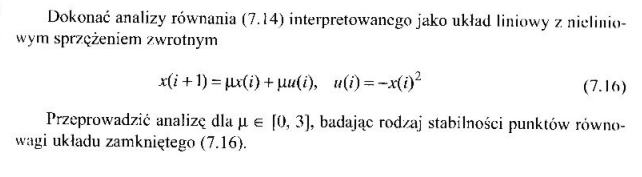

% i = 1000;
% Ap = mi(i);
% Bp = mi(i);
% Cp = 1;
% Dp = 0;
% 
% sys = ss(Ap, Bp, Cp, Dp, -1)
% sys_z = feedback(sys, )
% isstable(sys)

% tf_z = feedback(ss2tf(), )

N = 1000;
mi = linspace(0, 3, N);

mi =          0    0.0030    0.0060    0.0090    0.0120    0.0150    0.0180    0.0210    0.0240    0.0270    0.0300    0.0330    0.0360    0.0390    0.0420    0.0450    0.0480    0.0511    0.0541    0.0571    0.0601    0.0631    0.0661    0.0691    0.0721    0.0751    0.0781    0.0811    0.0841    0.0871    0.0901    0.0931    0.0961    0.0991    0.1021    0.1051    0.1081    0.1111    0.1141    0.1171    0.1201    0.1231    0.1261    0.1291    0.1321    0.1351    0.1381    0.1411    0.1441    0.1471


stany_ust = zeros(1, N);

stany_ust =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


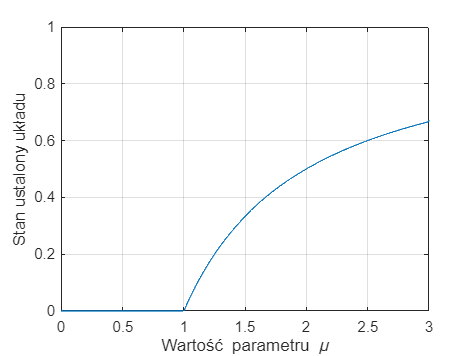


for i = 1 : N
    x = zeros(1, N);
    x(1) = 0.5;
    for j = 2 : N
        x(j) = mi(i) * x(j - 1) + mi(i) * -(x(j - 1) ^ 2);
    end
    % Stan ustalony
    stany_ust(i) = x(N);
end

figure;
plot(mi, stany_ust); grid on;
xlabel("Wartość parametru \mu");
ylabel("Stan ustalony układu");
ylim([0 1])